# Abundance-growth space of a bioleaching community: analysis of multiple scenarios

## Author(s): Sebastián N. Mendoza, Center for Mathematical Modeling, University of Chile, Chile. MATLAB implementation based on the Python code and tutorials of N.E. Jiménez et al. ([https://github.com/mathomics/ecosystem](https://github.com/mathomics/ecosystem))

## Reviewer(s):

## INTRODUCTION

Jiménez et al. [1] applied the abundance-growth framework to a bioleaching community composed of the iron oxidizer *Acidithiobacillus ferrooxidans* Wenelen (model *i_ML510, prefix* `wen`*) and the sulfur oxidizer _Sulfobacillus thermosulfidooxidans* Cutipay (model _i_SM517, prefix `cut`). Several scenarios were simulated, varying the supply of ferrous iron (Fe(II)) and thiosulfate, the energy level of the medium, the biological constraints and the parameter alpha, which defines the fraction of the carbon fixed by the community that is released as exopolysaccharides (EPS) and used by the heterotrophic growth of Cutipay.

Computing the qualitative flux variability analysis (FVA) of a grid of 50 x 50 points for many scenarios is computationally demanding, and the authors computed it in batches in a cluster. The results are distributed in the folder `result_files` of the repository of the paper. In this tutorial (notebook `sup_mat_multiple_bioleaching.ipynb` of [1]) we load these results, cluster the grid points of three scenarios that differ in alpha (0.2, 0.4 and 0.6), and compare their qualitative metabolic phenotypes.

The results of each scenario [`name`](#name) are stored as:

- [`name`](#name)`.p`: Python pickle with the grid points, member prefixes and objectives, member reactions and analyzed reactions.

- [`name`](#name)`.json`: community model in cobrapy JSON format.

- [`name`](#name)`_fpoints_<first>_<last>.npy`: feasibility of the grid points.

- [`name`](#name)`_qFVA_feasibleOnly_<first>_<last>.npy`: qualitative vectors.

- [`name`](#name)`_full_FVA_feasibleOnly_<first>_<last>.npy`: FVA results.

These files are read in MATLAB, without Python, with `readPythonPickle`, `readNumpyArray` and `readCobrapyJSONModel`. The feasibility files of the scenario with alpha = 0.2 are not included in the repository; `loadEcosystemScenario` recomputes the feasibility of its grid points with the community model and checks it against the number of qualitative vectors stored in each batch.

## MATERIALS - EQUIPMENT SETUP

- MATLAB. No additional MATLAB toolbox is required.

- The COBRA Toolbox, initialized with `initCobraToolbox`. The functions used in this tutorial are in the folders `src/analysis/ecosystem` and `src/base/io/utilities` (readers of Python files).

- A solver for linear programming problems (only needed to recompute the feasibility of the scenario with alpha = 0.2 and the maximum flux of a reaction in Step 5).

- A local copy of the repository [https://github.com/mathomics/ecosystem](https://github.com/mathomics/ecosystem) (folder `result_files` and file `simulations_pareto4.csv`). Set the variable `ecosystemRepoDir` to its location before running the tutorial; otherwise, the version of the repository used in this tutorial is downloaded (~35 MB) to a temporary folder.

global CBTDIR
if isempty(CBTDIR)
    initCobraToolbox(false);
end
% use Gurobi if available, GLPK otherwise
if ~changeCobraSolver('gurobi', 'LP', 0)
    changeCobraSolver('glpk', 'LP');
end
% solver tolerances of 1e-7 (default tolerance of cobrapy, used by the Python implementation)
changeCobraSolverParams('LP', 'optTol', 1e-7);
changeCobraSolverParams('LP', 'feasTol', 1e-7);
% path to a local copy of https://github.com/mathomics/ecosystem
if ~exist('ecosystemRepoDir', 'var') || isempty(ecosystemRepoDir)
    ecosystemRepoDir = '';
end
if ~exist(fullfile(ecosystemRepoDir, 'result_files'), 'dir')
    ecosystemCommit = '9be53a49a57ecad5e3a38ff2ac91e16bac747335';
    ecosystemRepoDir = fullfile(tempdir, ['ecosystem-' ecosystemCommit]);
    if ~exist(fullfile(ecosystemRepoDir, 'result_files'), 'dir')
        fprintf('Downloading https://github.com/mathomics/ecosystem (~35 MB) ...\n');
        zipFile = websave(fullfile(tempdir, ['ecosystem-' ecosystemCommit '.zip']), ...
            ['https://github.com/mathomics/ecosystem/archive/' ecosystemCommit '.zip']);
        unzip(zipFile, tempdir);
        delete(zipFile);
    end
end
resultDir = fullfile(ecosystemRepoDir, 'result_files');

## PROCEDURE

## Step 1: Load and filter the table of simulated scenarios

**TIMING**: < 1 s

The file `simulations_pareto4.csv` describes the simulated scenarios. As in the original notebook, file names are made consistent with the names of the result files (`a0_` -> `a00_`, `a0,` -> `a0` and `,` -> `.`).

csvFile = fullfile(ecosystemRepoDir, 'simulations_pareto4.csv');
opts = detectImportOptions(csvFile, 'Delimiter', ';', 'Encoding', 'UTF-8', 'VariableNamingRule', 'preserve');
opts = setvartype(opts, 'char');
simulations = readtable(csvFile, opts);
simulations.Filename = regexprep(simulations.Filename, 'a0_', 'a00_');
simulations.Filename = regexprep(simulations.Filename, 'a0,', 'a0');
simulations.Filename = regexprep(simulations.Filename, ',', '.');
tail(simulations, 5)

ans = 5x12 table
     Alpha         Substrate combination         input constraint    Input Fe    Input S    Coef Fe    Coef S     Energy level                             Filename                                  Objective           Status        Repeat  
    _______    ______________________________    ________________    ________    _______    _______    _______    ____________    __________________________________________________________    ___________________    __________    __________

    {'0,2'}    {'0.5_Fe_medium_0.5_S_medium'}      {'biocons'}        {'75'}      {'5'}     {'

Scenarios are selected by alpha, input constraint (biological constraints `biocons` or unconstrained `uncons`), energy level and substrate combination (fractions of Fe(II) and thiosulfate supply). Scenarios with alternative objectives are discarded when `obj` is empty.

params = struct();
params.alpha = [0.2, 0.4, 0.6];
params.obj = {};
params.cons = {'biocons'};
params.energy = {'Medium'};
params.subCombs = [0.5, 0.5];
params.flag = {};
params.k = 20;            % number of clusters
params.threshold = 0.8;   % threshold for representative states
scenarios = filterEcosystemScenarios(simulations, params)

scenarios = 3x1 cell array
    {'biomin_newgrid_sce_a02_biocons_75Fe_5S'}
    {'biomin_newgrid_sce_a04_biocons_75Fe_5S'}
    {'biomin_newgrid_sce_a06_biocons_75Fe_5S'}


## Step 2: Load the results of each scenario

**TIMING**: ~10 s per scenario (~5 min for the scenario that requires recomputing the feasibility of 2,499 points with GLPK)

For each scenario: (i) the results are loaded, (ii) only exchange reactions are kept for clustering, (iii) points with null community growth and points with a single member (f = 0 or f = 1) are removed and (iv) the grid points are clustered in `k` clusters.

**CRITICAL STEP**: the qualitative vectors of these scenarios were computed with a threshold delta = 1e-4 (`multiple_ecosystem.py`). Use the same threshold if you recompute them with `ecosystemQualitativeFVA`.

ecoList = cell(numel(scenarios), 1);
for i = 1:numel(scenarios)
    eco = loadEcosystemScenario(resultDir, scenarios{i}, 'batchSize', 250);
    eco = selectEcosystemReactions(eco, contains(eco.rxn2cluster, 'EX_'));
    toRemove = eco.points(:, 2) == 0 | eco.pfractions(:, 1) == 1 | eco.pfractions(:, 1) == 0;
    eco = removeEcosystemPoints(eco, toRemove);
    eco = clusterEcosystemPoints(eco, 'method', 'hierarchical', 'k', params.k);
    ecoList{i} = eco;
end

biomin_newgrid_sce_a02_biocons_75Fe_5S
Feasibility files not found. Recomputing the feasibility of 2499 grid points...
grid feasible points: 1963 / 2499
  grid points: 2499, feasible: 1963 (recomputed), reactions: 1255, FVA results: false


Calculating jaccard distances between grid points...
Clustering grid points ...
Done!


biomin_newgrid_sce_a04_biocons_75Fe_5S
  grid points: 2499, feasible: 1874 (files), reactions: 1255, FVA results: true


Calculating jaccard distances between grid points...
Clustering grid points ...
Done!


biomin_newgrid_sce_a06_biocons_75Fe_5S
  grid points: 2499, feasible: 1732 (files), reactions: 1255, FVA results: true


Calculating jaccard distances between grid points...
Clustering grid points ...
Done!


## Step 3: Clusters of a single scenario

**TIMING**: < 1 s

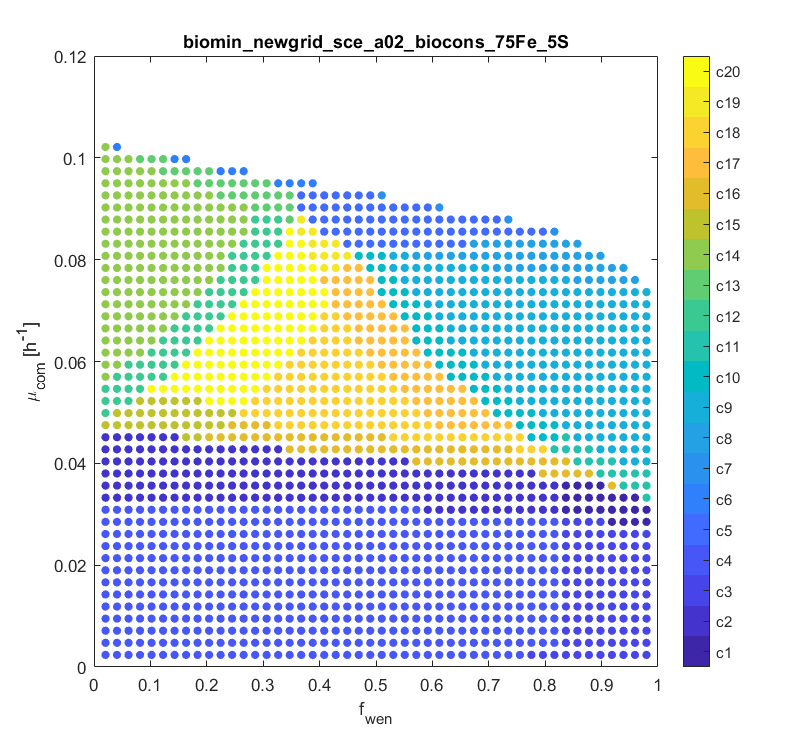

eco = ecoList{1};
plotEcosystemGrid(eco, 'toPlot', 'cluster', 'colormap', 'parula', 'markerSize', 25, ...
    'xlabel', 'f_{wen}', 'title', eco.name);

## Step 4: Clusters of all the scenarios

**TIMING**: < 1 s

Cluster labels of independent clusterings are arbitrary. To compare scenarios, the clusters of each scenario can be relabeled to match those of a reference scenario with the same representative qualitative states (`matchEcosystemClusters`); clusters without a match receive new labels.

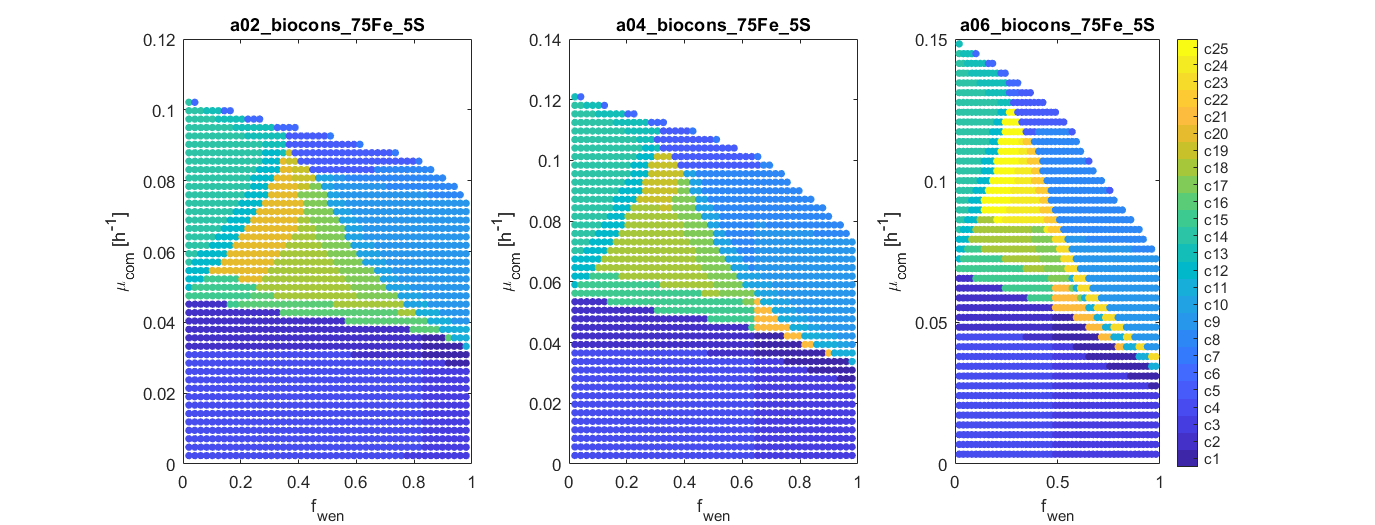

[~, refValues, refRxnIds] = getEcosystemClusterReactionValues(ecoList{1}, 'thr', params.threshold, 'changing', true);
matchedClusters = cell(numel(ecoList), 1);
for i = 1:numel(ecoList)
    [~, values, ids] = getEcosystemClusterReactionValues(ecoList{i}, 'thr', params.threshold, 'changing', true);
    [matchedClusters{i}, refValues] = matchEcosystemClusters(refValues, refRxnIds, values, ids, ecoList{i}.clusters);
end
nTotalClusters = size(refValues, 2);
figure('Position', [100, 100, 1100, 420]);
for i = 1:numel(ecoList)
    ax = subplot(1, numel(ecoList), i);
    ecoPlot = ecoList{i};
    ecoPlot.k = nTotalClusters;
    plotEcosystemGrid(ecoPlot, 'toPlot', 'cluster', 'clusters', matchedClusters{i}, 'axes', ax, ...
        'colormap', 'parula', 'markerSize', 20, 'xlabel', 'f_{wen}', 'title', strrep(ecoPlot.name, 'biomin_newgrid_sce_', ''), ...
        'showColorbar', i == numel(ecoList));
end

## Step 5: Flux values of a reaction on the grid

**TIMING**: < 1 s if FVA results are available; ~1 min otherwise (Gurobi)

The maximum flux of EPS exchange (`EX_eps_AFE_e`) on the grid. FVA results are not distributed for the scenario with alpha = 0.2, so the maximum flux of this reaction is computed by maximizing it at each point with the community model.

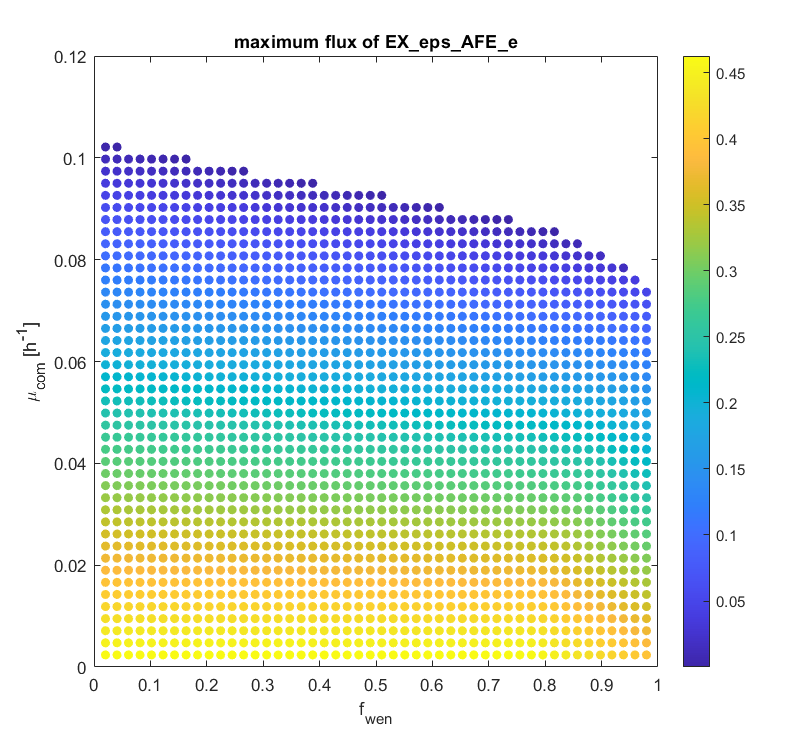

rxn = 'EX_eps_AFE_e';
col = find(strcmp(eco.rxn2cluster, rxn));
if ~isempty(eco.fvaResults)
    maxEPS = eco.fvaResults(:, col, 2);
else
    maxEPS = NaN(numel(eco.qualPointIndex), 1);
    for p = 1:numel(eco.qualPointIndex)
        modelPoint = constrainEcosystemPoint(eco, eco.points(eco.qualPointIndex(p), :));
        modelPoint = changeObjective(modelPoint, rxn);
        sol = optimizeCbModel(modelPoint, 'max');
        if sol.stat == 1
            maxEPS(p) = sol.f;
        end
    end
end
plotEcosystemGrid(eco, 'toPlot', 'values', 'values', maxEPS, 'colormap', 'parula', 'markerSize', 30, ...
    'xlabel', 'f_{wen}', 'title', ['maximum flux of ' rxn]);

## Step 6: Overlap of qualitative states in several scenarios

**TIMING**: < 1 s

The qualitative states of one or several reactions are encoded for each point and plotted for all the scenarios with a common color code. First, the CO2 exchange of Cutipay:

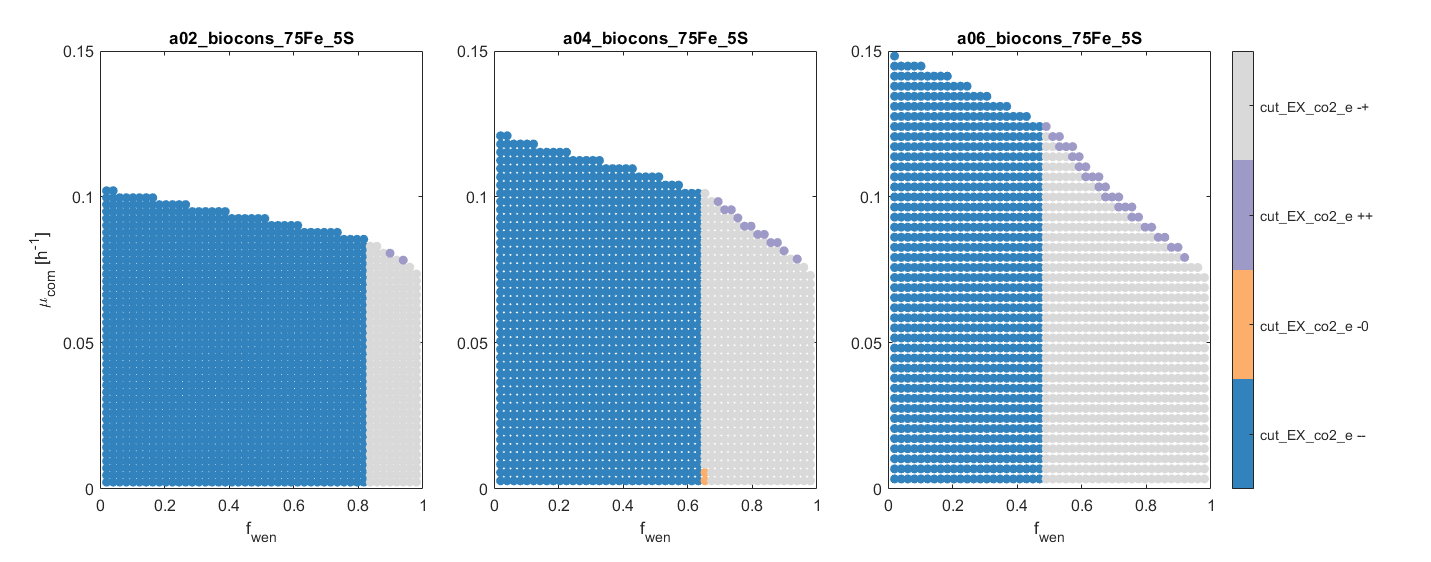

plotQualitativeStateOverlap(ecoList, {'cut_EX_co2_e'}, 'xlabel', 'f_{wen}', ...
    'titles', strrep(scenarios, 'biomin_newgrid_sce_', ''));

Then, the combination of the CO2 exchange of Cutipay and the community exchanges of Fe(II) and thiosulfate:

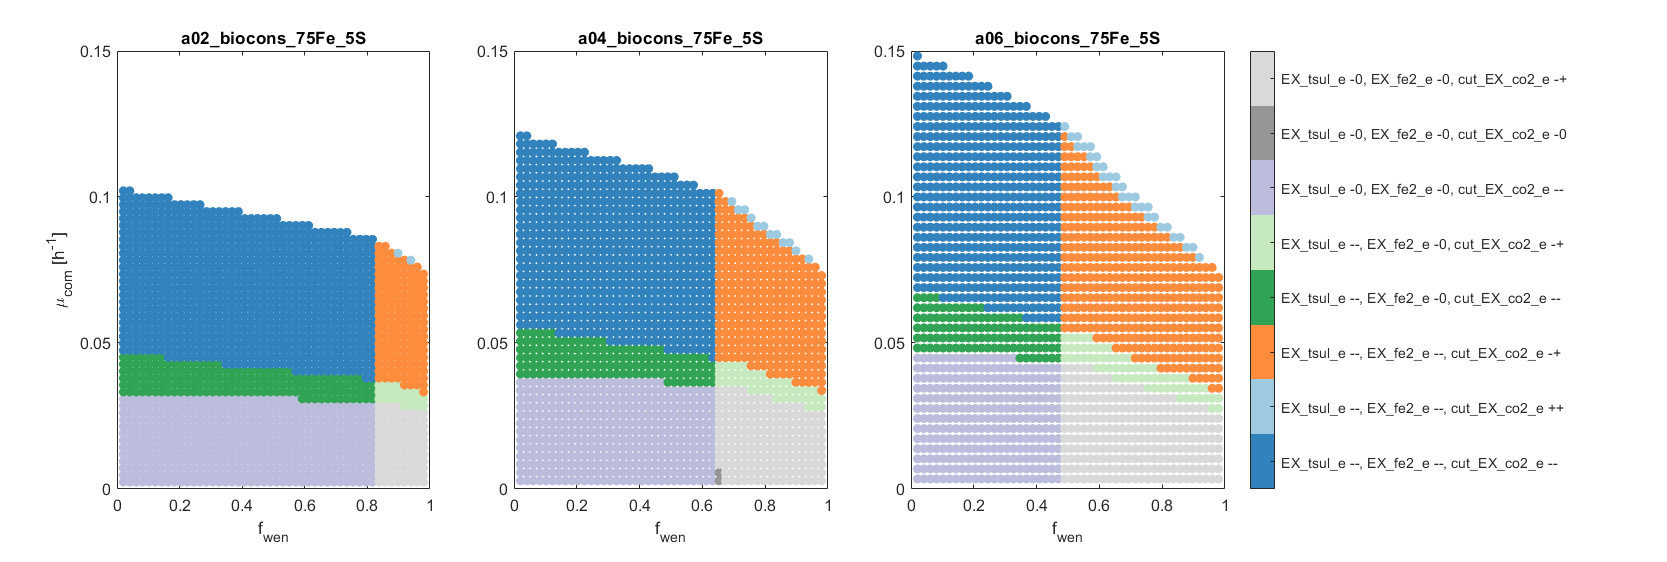

[~, stateCodes, stateLabels] = plotQualitativeStateOverlap(ecoList, {'cut_EX_co2_e', 'EX_fe2_e', 'EX_tsul_e'}, ...
    'xlabel', 'f_{wen}', 'titles', strrep(scenarios, 'biomin_newgrid_sce_', ''));

stateLabels

stateLabels = 8x1 cell array
    {'EX_tsul_e --, EX_fe2_e --, cut_EX_co2_e --'}
    {'EX_tsul_e --, EX_fe2_e --, cut_EX_co2_e ++'}
    {'EX_tsul_e --, EX_fe2_e --, cut_EX_co2_e -+'}
    {'EX_tsul_e --, EX_fe2_e -0, cut_EX_co2_e --'}
    {'EX_tsul_e --, EX_fe2_e -0, cut_EX_co2_e -+'}
    {'EX_tsul_e -0, EX_fe2_e -0, cut_EX_co2_e --'}
    {'EX_tsul_e -0, EX_fe2_e -0, cut_EX_co2_e -0'}
    {'EX_tsul_e -0, EX_fe2_e -0, cut_EX_co2_e -+'}


## Step 7: Key reaction candidates of a scenario

**TIMING**: < 1 s

The representative states of the exchange reactions that change among the clusters of the first scenario (alpha = 0.2) are candidates for key reactions of the scenario:

eco = ecoList{1};
[repTable, repValues, rxnIds] = getEcosystemClusterReactionValues(eco, 'thr', params.threshold, 'changing', true)

repTable = 29x20 table
                          c1        c2        c3        c4        c5        c6         c7         c8         c9        c10        c11       c12       c13        c14        c15       c16       c17        c18        c19       c20  
                        ______    ______    ______    ______    ______    _______    _______    _______    _______    ______    _______    ______    ______    _______   

repValues =      1     1     1     1     1     1   NaN     1     1     1     1     1     1     1     1     1     1     1     1     1
    -1    -1    -1    -1    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2
     1     1     1     1     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2
     1     1     1     1     1     1   NaN     1     1     1     1     1     1     1     1     1     1     1     1     1
     4     4     4     4    -2    -2    -2    -2    -2    -2     4    -2    -2    -2     4     4    -2   NaN    -2    -2
    -2    -2    -2    -2    -2   NaN    -3    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2
     1     1     1     1     2     2     2     2     2     2   NaN     2     2     2   NaN     1     2     2     2     2
     1     1     1     1     1     1   NaN     1     1     1     1     1     1     1     1     1     1     1     1     1
    -2    -2    -1  

rxnIds = 29x1 cell array
    {'EX_eps_AFE_e'    }
    {'EX_fe2_e'        }
    {'EX_fe3_e'        }
    {'EX_glc_pool'     }
    {'EX_h_e'          }
    {'EX_nh4_e'        }
    {'EX_so4_e'        }
    {'EX_succ_c'       }
    {'EX_tsul_e'       }
    {'cut_EX_co2_e'    }
    {'cut_EX_eps_AFE_e'}
    {'cut_EX_fe2_e'    }
    {'cut_EX_fe3_e'    }
    {'cut_EX_glc_e'    }
    {'cut_EX_h2o_e'    }
    {'cut_EX_h_e'      }
    {'cut_EX_nh4_e'    }
    {'cut_EX_so4_e'    }
    {'cut_EX_so4aa_e'  }
    {'cut_EX_tsul_e'   }
    {'wen_EX_eps_AFE_e'}
    {'wen_EX_fe2_e'    }
    {'wen_EX_fe3_e'    }
    {'wen_EX_h2o_e'    }
    {'wen_EX_h_e'      }
    {'wen_EX_nh4_e'    }
    {'wen_EX_pi_e'     }
    {'wen_EX_so4_e'    }
    {'wen_EX_tsul_e'   }


Reactions that change between two clusters (e.g. clusters 5 and 4):

compareEcosystemClusters(repValues, rxnIds, 'c5', 'c4')

ans = 14x2 table
                       c5        c4  
                     ______    ______

    EX_fe2_e         {'--'}    {'-0'}
    EX_fe3_e         {'++'}    {'0+'}
    EX_h_e           {'--'}    {'-+'}
    EX_so4_e         {'++'}    {'0+'}
    EX_tsul_e        {'--'}    {'-0'}
    cut_EX_glc_e     {'--'}    {'-0'}
    cut_EX_so4_e     {'++'}    {'0+'}
    cut_EX_tsul_e    {'--'}    {'-0'}
    wen_EX_fe2_e     {'--'}    {'-0'}
    wen_EX_fe3_e     {'++'}    {'0+'}
    wen_EX_h2o_e     {'++'}    {'-+'}
    wen_EX_h_e       {'--'}    {'-+'}
    wen_EX_so4_e     {'++'}    {'0+'}
    wen_EX_tsul_e    {'--'}    {'-0'}


## Step 8: Cluster descriptors

**TIMING**: < 1 s

`getEcosystemClusterDescriptor` shows which reaction states are more descriptive of a cluster: for each reaction, it counts in how many clusters the reaction has a different representative state.

getEcosystemClusterDescriptor(repValues, rxnIds, 'c14')

ans = 29x2 table
                     status_c14    diff
                     __________    ____

    cut_EX_h2o_e       {'++'}       17 
    cut_EX_h_e         {'--'}       17 
    cut_EX_fe2_e       {'--'}       16 
    cut_EX_fe3_e       {'++'}       16 
    cut_EX_so4_e       {'++'}       13 
    wen_EX_tsul_e      {'-0'}       12 
    cut_EX_tsul_e      {'--'}       11 
    wen_EX_so4_e       {'0+'}       10 
    EX_h_e             {'--'}        8 
    EX_so4_e           {'++'}        7 
    wen_EX_fe2_e       {'-0'}        7 
    wen_EX_fe3_e       {'0+'}        7 
    cut_EX_co2_e       {'--'}        5 
    wen_EX_h2o_e       {'-+'}        5 
    wen_EX_h_e     

## TROUBLESHOOTING

- **Problem**: `loadEcosystemScenario` warns that the number of qualitative vectors of a batch differs from the number of feasible points. **Possible reason**: the feasibility was recomputed with different numerical tolerances. **Solution**: use a different LP solver or check the solver tolerances (`changeCobraSolverParams`).

- **Problem**: the download of the repository fails or MATLAB stops during the download (observed with `websave` of MATLAB R2021a on Windows). **Solution**: clone [https://github.com/mathomics/ecosystem](https://github.com/mathomics/ecosystem) manually (or download it as a zip file from GitHub) and set the variable `ecosystemRepoDir` to its location before running the tutorial.

- **Problem**: cluster labels differ from those of the original notebook. **Possible reason**: the feasibility of the scenario with alpha = 0.2 is recomputed, and small numerical differences between LP solvers can change the points that are clustered (the clustering itself gives the same labels as SciPy). **Solution**: compare clusters through their representative states.

## TIMING

- Step 1: < 1 s

- Step 2: ~1 min (Gurobi), including the recomputation of the feasibility of one scenario (~5 min with GLPK)

- Steps 3-4: ~5 s

- Step 5: ~1 min (Gurobi) if the maximum flux has to be computed

- Steps 6-8: ~5 s

## ANTICIPATED RESULTS

The scenarios selected are `biomin_newgrid_sce_a02_biocons_75Fe_5S`, `biomin_newgrid_sce_a04_biocons_75Fe_5S` and `biomin_newgrid_sce_a06_biocons_75Fe_5S`. Each grid has 2,499 points and 1,255 analyzed reactions, of which 68 are exchange reactions. The recomputed feasibility of the scenario with alpha = 0.2 gives 1,963 feasible points, consistent batch by batch with the stored qualitative vectors (the feasibility recomputed for alpha = 0.4 is identical to the stored one). After removing the points with null growth or a single member, 1,840, 1,756 and 1,619 points are clustered for alpha = 0.2, 0.4 and 0.6.

The table of representative states of the scenario with alpha = 0.2 (29 exchange reactions that change among the 20 clusters) is identical to that of the original notebook. Clusters 4 and 5 differ in 14 reactions, mainly the exchanges of Fe(II), Fe(III), protons, sulfate and thiosulfate (from `-0`/|0+| to `--`/|++|), i.e. in the activity of iron and sulfur oxidation. Cluster 14 is characterized by the exchanges of water, protons, Fe(II) and Fe(III) of Cutipay, whose states differ from those of 16-17 of the 20 clusters, as in the original notebook.

## REFERENCES

[1] Jiménez, N.E., Acuña, V., Cortés, M.P., Eveillard, D., Maass, A. Unveiling abundance-dependent metabolic phenotypes of microbial communities. *mSystems* **8**, e00492-23 (2023).